Experiment with amino acid compositions from real-world enzymes

%load the data
aminos = {'ala__L_c' 'arg__L_c' 'asn__L_c' 'asp__L_c' 'cys__L_c' 'gln__L_c' 'glu__L_c'...
    'gly_c' 'his__L_c' 'ile__L_c' 'leu__L_c' 'lys__L_c' 'met__L_c' 'phe__L_c' 'pro__L_c' ...
    'ser__L_c' 'thr__L_c' 'trp__L_c' 'tyr__L_c' 'val__L_c'};
aadat = readtable('C:\sync\biomes\cellulose\optima\aminos\enzyme_AAs.txt','Format','%s%s%s%s%s%s');
aanames = {'Alanine (A)' 'Arginine (R)' 'Asparagine (N)' 'Aspartic acid (D)' 'Cysteine (C)'...
'Glutamine (Q)' 'Glutamic acid (E)' 'Glycine (G)' 'Histidine (H)' 'Isoleucine (I)'...
'Leucine (L)' 'Lysine (K)' 'Methionine (M)' 'Phenylalanine (F)' 'Proline (P)'...
'Serine (S)' 'Threonine (T)' 'Tryptophan (W)' 'Tyrosine (Y)' 'Valine (V)'};

%from Akashi & Gojobori 2002
costs = [11.7 27.3 14.7 12.7 24.7 16.3 15.3 11.7 39.3 32.3 27.3 30.3 34.3 52.0 20.3 11.7 18.7 74.3 50 23.3];
[sortedcosts, costidx] = sort(costs);

%format some data
aadat.seqlength = cellfun(@(x) length(x),aadat.sequence);
[nrows ncols] = size(aadat);
aadat.class = cell(nrows,1);
aadat.class(strcmp('3.2.1.4',aadat.ec)) = {'endoglucanase'};
aadat.class(strcmp('3.2.1.21',aadat.ec)) = {'glucosidase'};
aadat.class(strcmp('3.2.1.91',aadat.ec)) = {'exoglucanase'};


%get the composition of the proteins
for i = 1:nrows
    aaseq = aadat.sequence{i};
    c = zeros(20,1);
    c(1) = count(aaseq,'A');
    c(2) = count(aaseq,'R');
    c(3) = count(aaseq,'N');
    c(4) = count(aaseq,'D');
    c(5) = count(aaseq,'C');
    c(6) = count(aaseq,'Q');
    c(7) = count(aaseq,'E');
    c(8) = count(aaseq,'G');
    c(9) = count(aaseq,'H');
    c(10) = count(aaseq,'I');
    c(11) = count(aaseq,'L');
    c(12) = count(aaseq,'K');
    c(13) = count(aaseq,'M');
    c(14) = count(aaseq,'F');
    c(15) = count(aaseq,'P');
    c(16) = count(aaseq,'S');
    c(17) = count(aaseq,'T');
    c(18) = count(aaseq,'W');
    c(19) = count(aaseq,'Y');
    c(20) = count(aaseq,'V');
    aadat.aa_counts{i} = c;
    aadat.composition{i} = c / aadat.seqlength(i);
end


Some plots to examine the general shape of the distributions

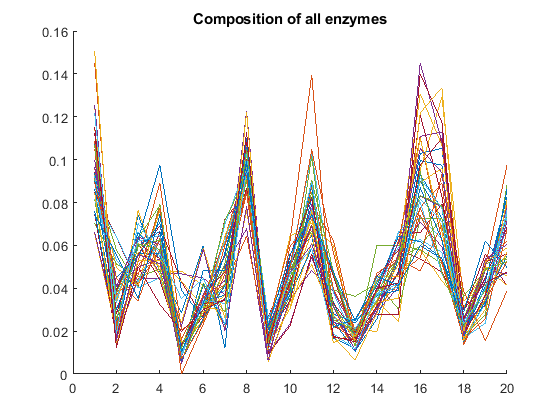

figure();
hold on;
for i = 1:nrows
    plot(aadat.composition{i});
end
xticks = 1:20;
xticklabels = aminos;
title('Composition of all enzymes');
hold off;

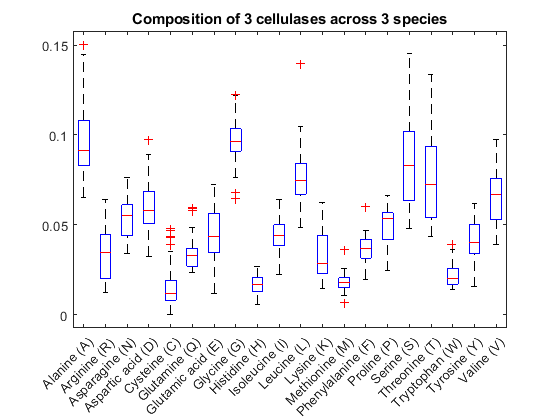

[nseries,~] = size(aadat.composition);
boxdat = zeros(nseries,20);
for i = 1:nseries
    boxdat(i,:) = aadat.composition{i};
end
bp = boxplot(boxdat,aanames);
set(gca,'XTickLabelRotation',45);
title('Composition of 3 cellulases across 3 species')

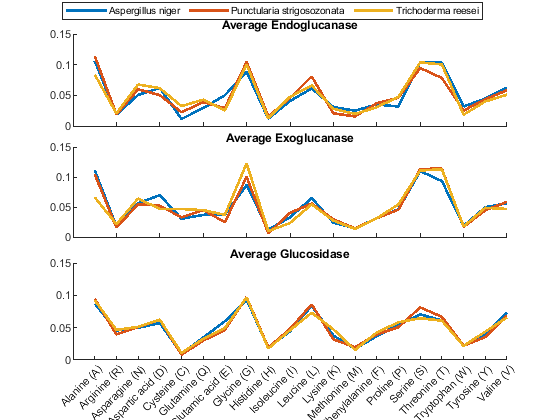


species = unique(aadat.species);
figure1 = figure();
axes1 = axes('Parent',figure1,...
    'Position',[0.13 0.700626959247649 0.775 0.21880857925822]);
hold(axes1,'on');
for i = 1:length(species)
    spec = species{i};
    subtab = aadat(strcmp(spec,aadat.species),:);
    endo{i} = mean(horzcat(subtab(strcmp('endoglucanase',subtab.class),:).composition{:}),2);
    exo{i} = mean(horzcat(subtab(strcmp('exoglucanase',subtab.class),:).composition{:}),2);
    glu{i} = mean(horzcat(subtab(strcmp('glucosidase',subtab.class),:).composition{:}),2);
end
%subplot(3,1,1);
avgendo = horzcat(endo{:});
p.a = plot(avgendo,'linewidth',2);
ylim([0,.15]);
ax = gca;
set(ax,'XTickLabel',{'','','','','','','','','','',''});

% for i = 1:length(species)
%     row = endo{i};
%     plot(mean(horzcat(row.composition{:}),2));
    title('Average Endoglucanase');
% end
%subplot(3,1,2);
axes2 = axes('Parent',figure1,...
    'Position',[0.13 0.435736677115987 0.775 0.213166144200627]);
hold(axes2,'on');
avgexo = horzcat(exo{:});
p.b = plot(avgexo,'linewidth',2);
ylim([0,.15]);
ax = gca;
set(ax,'XTickLabel',{'','','','','','','','','','',''});
% for i = 1:length(species)
%     row = exo{i};
%     plot(mean(horzcat(row.composition{:}),2));
    title('Average Exoglucanase');
% end
%subplot3 = subplot(3,1,3);
axes3 = axes('Parent',figure1,...
    'Position',[0.13 0.143574229264551 0.775 0.231033921205668]);
hold(axes3,'on');
avgglu = horzcat(glu{:});
p.c = plot(avgglu,'linewidth',2);
ylim([0,.15]);
% for i = 1:length(species)
%     row = glu{i};
%     plot(mean(horzcat(row.composition{:}),2));
    title('Average Glucosidase');
% end
set(axes3,'XTick',[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20],...
    'XTickLabel',aanames,'XTickLabelRotation',45);
for i = 1:length(species)
    set(p.c(i),'DisplayName',species{i});
end
legend1 = legend(axes3,'show');
set(legend1,...
    'Position',[0.320340733321437 0.958267148100047 0.331034478935701 0.0322846686026822],...
    'Orientation','horizontal');
hold off;

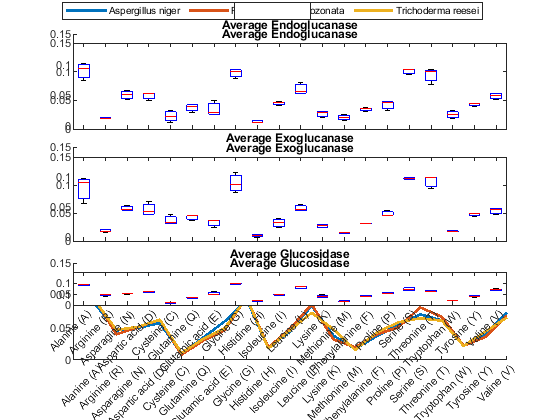

axes1 = axes('Parent',figure1,...
    'Position',[0.13 0.700626959247649 0.775 0.21880857925822]);
hold(axes1,'on');
avgendo = horzcat(endo{:});
p.a = boxplot(avgendo');
ylim([0,.15]);
ax = gca;
set(ax,'XTickLabel',{'','','','','','','','','','',''});

    title('Average Endoglucanase');
axes2 = axes('Parent',figure1,...
    'Position',[0.13 0.435736677115987 0.775 0.213166144200627]);
hold(axes2,'on');
avgexo = horzcat(exo{:});
p.b = boxplot(avgexo');
ylim([0,.15]);
ax = gca;
set(ax,'XTickLabel',{'','','','','','','','','','',''});
    title('Average Exoglucanase');
axes3 = axes('Parent',figure1,...
    'Position',[0.13 0.143574229264551 0.775 0.231033921205668]);
hold(axes3,'on');
avgglu = horzcat(glu{:});
p.c = boxplot(avgglu');
ylim([0,.15]);
    title('Average Glucosidase');
set(axes3,'XTick',[1 2 3 4 5 6 7 8 9 10 11 12 13 14 15 16 17 18 19 20],...
    'XTickLabel',aanames,'XTickLabelRotation',45);
for i = 1:length(species)
    set(p.c(i),'DisplayName',species{i});
end
legend1 = legend(axes3,'show');
set(legend1,...
    'Position',[0.320340733321437 0.958267148100047 0.331034478935701 0.0322846686026822],...
    'Orientation','horizontal');
hold off;

%Get some stats
highestincidence = zeros(20,3);
highestincidence_allclasses = zeros(20,1);
for i = 1:nrows
    for j = 1:20
        incidence = aadat.composition{i}(j);
        class = stridx(aadat.class{i},unique(aadat.class));
        if incidence > highestincidence(j,class)
            highestincidence(j,class) = incidence;
        end
        if incidence > highestincidence_allclasses(j)
            highestincidence_allclasses(j) = incidence;
        end
    end
end
lowestincidence = ones(20,3);
lowestincidence_allclasses = ones(20,1);
for i = 1:nrows
    for j = 1:20
        incidence = aadat.composition{i}(j);
        class = stridx(aadat.class{i},unique(aadat.class));
        if incidence < lowestincidence(j,class)
            lowestincidence(j,class) = incidence;
        end
        if incidence < lowestincidence_allclasses(j)
            lowestincidence_allclasses(j) = incidence;
        end
    end
end
unique(aadat.class)

ans = 3×1 cell array
    {'endoglucanase'}
    {'exoglucanase' }
    {'glucosidase'  }

incidencediff = highestincidence - lowestincidence

incidencediff =     0.0590    0.0842    0.0440
    0.0129    0.0083    0.0408
    0.0324    0.0136    0.0323
    0.0565    0.0507    0.0355
    0.0419    0.0306    0.0145
    0.0354    0.0328    0.0251
    0.0394    0.0212    0.0495
    0.0448    0.0582    0.0255
    0.0162    0.0093    0.0176
    0.0289    0.0246    0.0300


incidencediff_allclasses = highestincidence_allclasses - lowestincidence_allclasses

incidencediff_allclasses =     0.0850
    0.0515
    0.0422
    0.0649
    0.0479
    0.0366
    0.0604
    0.0582
    0.0211
    0.0418



biggestdiff_idx = find(incidencediff_allclasses == max(incidencediff_allclasses));
biggestrange = [lowestincidence_allclasses(biggestdiff_idx) highestincidence_allclasses(biggestdiff_idx)]

biggestrange =     0.0480    0.1451


rangefactor = biggestrange(2) / biggestrange(1)

rangefactor = 3.0247

The most variable AA, Serine, ranges from 4.8% to 14.5% of the protein, a 3.02-fold change.

Next, describe the average proteins:

endolength = mean(aadat.seqlength(strcmp('endoglucanase',aadat.class)))

endolength = 443.4444

exolength = mean(aadat.seqlength(strcmp('exoglucanase',aadat.class)))

exolength = 480.2857

glulength = mean(aadat.seqlength(strcmp('glucosidase',aadat.class)))

glulength = 733.6296

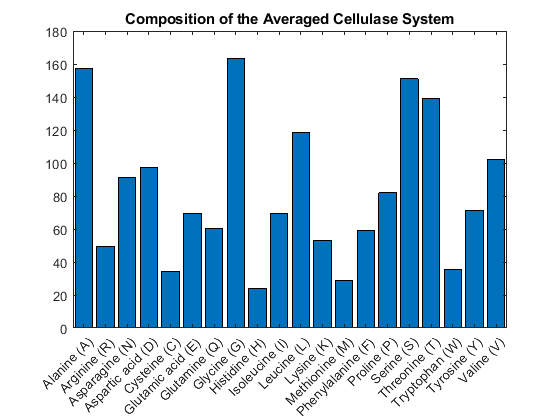


endocounts = mean(avgendo,2) * endolength;
exocounts = mean(avgexo,2) * exolength;
glucounts = mean(avgglu,2) * glulength;

totalcounts = endocounts+exocounts+glucounts;

c = categorical(aanames);
figure()
bar(c,totalcounts)
title('Composition of the Averaged Cellulase System')

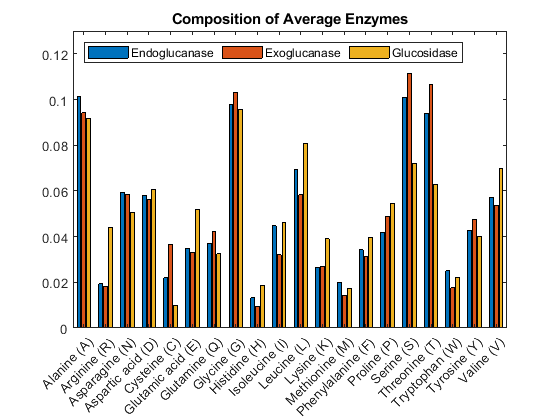



[~,abundancerank] = sort(totalcounts,'descend');
[~,abundancerank] = sort(abundancerank); %convert the order to the rank


figure()
bar(c,horzcat(mean(avgendo,2),mean(avgexo,2),mean(avgglu,2)));
legend('Endoglucanase','Exoglucanase','Glucosidase','orientation','horizontal','location','northwest');
title('Composition of Average Enzymes');
ylim([0 .13])

%Create plots with the amino acids sorted by metabolic cost
%Requires the 'order' and 'sortednames' variables from
%getRelativeAACosts.mlx

sc = categorical(sortednames,sortednames);

Undefined function or variable 'sortednames'.


figure();
hold on;
for i = 1:nrows
    plot(aadat.composition{i}(order));
end
xticks = 1:20;
xticklabels = sortednames;
title('Composition of all enzymes');
hold off;

figure()
bar(sc,totalcounts(order))
title('Composition of the Averaged Cellulase System')

figure()
a1 = avgendo(order,:);
a2 = avgexo(order,:);
a3 = avgglu(order,:);
bar(c,horzcat(mean(a1,2),mean(a2,2),mean(a3,2)));
legend('Endoglucanase','Exoglucanase','Glucosidase','orientation','horizontal','location','northwest');
title('Composition of Average Enzymes');
ylim([0 .13])